n_segments = 5;
rho_inner_base = 0.02;
rho_outer_base = 0.06;
rho_inner_tip = 0.02;
rho_outer_tip = 0.03;
l_0 = 0.5;
arm_series = ArmSeriesFactory.tapered_2d_antagonist_arm( ...
    n_segments, rho_inner_base, rho_outer_base, rho_inner_tip, rho_outer_tip, l_0...
);
arm_series.set_mechanics(BasicPolyBellowMechanics(l_0), [1, 4]);
arm_series.set_mechanics(GinaMuscleMechanics(l_0), [2, 3]);

p = [50; 0; 50; 0];
Q = [0; -5; 0];

equilibrium = arm_series.solve_equilibrium_gina(p, Q);


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>
Nonzero residual detected. Printing: 
   -0.0078   -0.0045   -0.0059   -0.0082   -0.0087
    0.0000    0.0000    0.0000   -0.0000   -0.0001
    0.3672    0.2132    0.2962    0.4190    0.4393


%arm_series.g_circ_right = equilibrium;

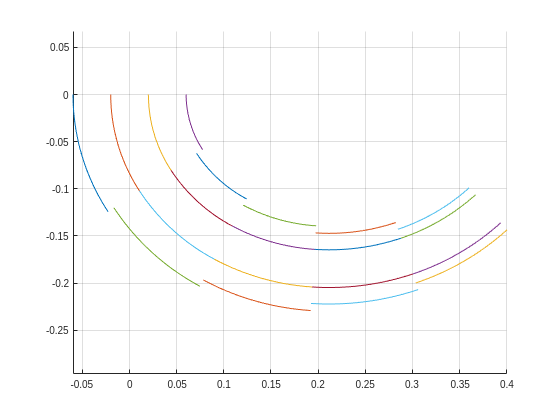

Plotter2D.plot_arm_series(arm_series, axes(figure()));

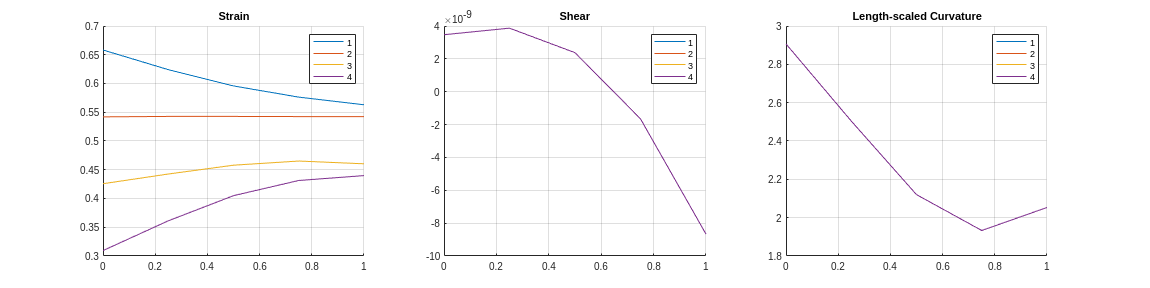

fig = figure();
set(fig, "Position", [0, 0, 1600, 400]);
Plotter2D.plot_g_circ_right(arm_series, fig);

% Plot where the muscles are in the strain-pressure space
E = arm_series.get_strains();

P = repmat(p, 1, arm_series.N_segments);
F = arm_series.get_forces(p);

% Let's plot the bellow strain/pressure along the rod onto its force
% surface

muscle_mechanics = GinaMuscleMechanics(l_0);


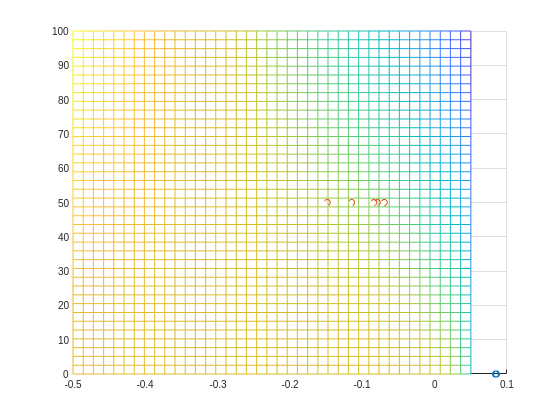

ax = axes(figure());
hold on
muscle_mechanics.plot_force_surface([-0.5, 0.05], [0, 100], ax)
scatter3(ax, E(2:3, :)', P(2:3, :)', F(2:3, :)')
grid on